## **Photovoltaic External Quantum Efficiency Analyser for Quantifying the Excitonic Static Disorder**

**Based on the Methodology Described in **Quantifying the Excitonic Static Disorder in Organic Semiconductors. *Adv. Funct. Mater.* 2022, 32, 2113181. [https://doi.org/10.1002/adfm.202113181](https://doi.org/10.1002/adfm.202113181)

*Austin M. Kay, Oskar J. Sandberg, Nasim Zarrabi, Wei Li, Stefan Zeiske, Christina Kaiser, Paul Meredith, Ardalan Armin*

Sustainable Advanced Materials (Sêr SAM), Department of Physics, Swansea University, Singleton Park, Swansea SA2 8PP, United Kingdom

*-----------------------------------------------------------------*

This program is free software. You can redistribute it and/or modify it under the terms of the GNU General Public License as published by the Free Software Foundation, either version of the License, or (at your option) any later version.

This program is distributed in the hope that it will be useful, but WITHOUT ANY WARRANTY; without even the implied warranty of MERCHANTABILITY or FITNESS FOR A PARTICULAR PURPOSE. See the GNU General Public License for more details.

You should have received a copy of the GNU General Public License along with this program.  If not, see <http://www.gnu.org/licenses/>.

----- **A Brief Description of the Script's Function **-----

This MATLAB script utilises the theory outlined in the 'Quantifying the Excitonic Static Disorder in Organic Semiconductors' maunscript to automate the process for quantifying energetic disorder in organic semiconductors. It does this by appling a modified version of the model for the sub-gap singlet exciton (*SE*) absorption coefficient derived by Kaiser *et al*. (in https://doi.org/10.1038298298/s41467-021-24202-9) to the appropriate spectral regime of photovoltaic external quantum efficiency spectra (*EQE*).

To estimate a value for the excitonic static disorder (*sigma*) from a given *EQE* spectrum (which can be dependent on either the photon wavelength or energy, the script will convert to the latter if need be). The script takes an estimate for the position of the first saturation peak (*FSP*) and the point at which the lineshape begins to be characterised by *SE*-absorption, i.e.,  the transition point (*tra*). The script also takes an estimate for the range in which these points may lie to optimize the fitting ranges. For example, in terms of photon energy, these could be *E_tra* = 1.5 +/- 0.1 eV and *E_FSP = *1.7 +/- 0.1 eV. 

The script then normalises the *EQE* spectrum with respect to its value at the *FSP* (which is identified using the estimate), before determining all combinations of minimum and maximum fitting limits within the estimate of the appropriate spectral regime. The script then conducts fittings on all th combinations of fitting limits that satisfy the specified minimum number of data points. Following this, the 'goodness-of-fit' parameter that describes how well the model describes the data in each fitting (the adjusted R-squared) is compared for all fittings. The fittings affected by the (sometimes) subtle absorption features of CT states and trap states are likely to result in deteriorated adjusted R-square values. Consequently, the "best" 20% of the fittings (in terms of adjusted R-squared) are sampled and a mean value for the excitonic static disorder is determined with an associated statistical uncertainty. All output variables, including the standard error in the fittings, are outputted to an Excel file entitled "Output.xlsx".

----- **Instructions for Use **-----

**(1) **For this MATLAB script to operate, the '*Analyser.xlsx*' Excel file must be prepared. Before entering data into the '*Analyser_Input*' sheet of the Excel file, it is best to clear any data from prior use. Once this has been done, the first entry (cell A2) of the '*Analyser_Input*' sheet should be entered as '0' or '1', depending on whether the independent variable is a function of photon wavelength or photon energy, respectively.

**(2) **Secondly, the active layer thickness in units of nanometres should be entered into the cell B2.

**(3)** Following this, the temperature should be calculated in units of Kelvin and entered into the cell C2. 

**(4)** The independent variable data should now be entered into the fourth column from cell D2. This can be either photon wavelength or photon energy data, as long as the correct specification is entered into cell A2.

**(5)** The dependent variable data (i.e., the photovoltaic external quantum efficiency measurements) should now be entered into the fifth column from cell E2.

**(6)** An estimate of either the minimum wavelength (in nanometres) or the maximum photon energy (in electronvolts) that identifies the first saturation peak should now be entered into the cell F2. This point should describe the upper limit of spectral regime charactersied by SE behaviour, and it should therefore be the onset of the sub-gap tail. The uncertainty in this estimate (for which the script will allow the upper variable to float by) should be estimated into the cell F4. For example, this upper limit could be *E_FSP = *1.7 +/- 0.1 eV.

**(7)** Following this, an estimate for the lower limit of the spectral regime characterised by SE behaviour should be entered into the cell G2. This should be either the maximum wavelength (in nanometres) or the minimum photon energy (in electronvolts). The uncertainty in this estimate should be entered into the cell G4. An example for the estimate of the transition to the SE-dominated regime could be *E_tra = *1.5 +/- 0.2 eV.

**(8)** The minimum number of data points required in the fitting should be entered into the cell H2. 

**(9) **This MATLAB script can now be run for a quantification of the excitonic static disorder from the input *EQE *spectrum.

----- **Part I** ----- 

Firstly, the workspace is cleared and some useful constants are defined.

clear,
close all
h = 6.62607004E-34;     % Planck's constant; units are Joule-seconds, Js.
c = 299792458;          % Speed of light in vacuum; units are metres-per-second, m/s.
e = 1.60217662E-19;     % Elementary charge; units are Coulombs, C.
k = 1.38064852E-23;     % Boltzmann's constant; units are Joule-per-Kelvin, J/K

Following this, the data is imported from the '*Analyser_Input*' sheet of the '*Excitonic_Disorder_Estimator_Input.xlsx*' Excel file. If necessary, the title and/or sheet name of the Excel file can be altered. The filename of the ouptut sheet is also specified here.

EQE_data_filename = 'Excitonic_Disorder_Estimator_Input.xlsx';
output_data_filename = 'Output.xlsx';
imported_data = xlsread( EQE_data_filename , 'Analyser_Input' );

From the imported data, the independent variable type (photon wavelength in nanometres or photon energy in electronvolts), the active layer thickness, and the thermal energy are specified.

independent_variable_specification = imported_data( 1 , 1 );    % First entry of first column
d_AL = imported_data( 1 , 2 );  % First entry of second column
temp = imported_data( 1 , 3 );  % First entry of third column
k_BT = k * temp / e;                      

Furthermore, the independent and dependent variable data are specified. 

independent_variable_data = imported_data( : , 4 );              % Fourth column
EQE_PV_data = imported_data( : , 5 );                            % Fifth column

The independent variable data and the estimate for the *FSP *and transition point are loaded in (where photon energy dependent data is initially assumed).

photon_energies = independent_variable_data;                % First, assume independent variable is photon energy
E_FSP_est = imported_data( 1 , 6 );                         % Initial estimate for First Saruation Peak (FSP)
E_FSP_float = imported_data( 3 , 6 );                       % Estimate for range in which FSP sits
E_tra_est = imported_data( 1 , 7 );                         % Initial estimate for transition (tra) between CT/trap state and SE behaviour
E_tra_float = imported_data( 3 , 7 );  
minimum_num_data_points = imported_data( 1 , 8 );

E_FSP_float_min = E_FSP_est - E_FSP_float;                  % Minimum fitting point according to uncertainty in estimate for E_tra
E_FSP_float_max = E_FSP_est + E_FSP_float;                  % Maximum value for the minimum fitting point

E_tra_float_min = E_tra_est - E_tra_float;                  % Minimum of the maximum fitting point, according to uncertainty in estimate for E_FSP
E_tra_float_max = E_tra_est + E_tra_float;                  % Absolute maximum fitting point according to uncertainty in estimate for E_FSP

As this script relies on photon energy-dependent data then, if need be, the photon wavelength data is converted to photon energy data. 

if independent_variable_specification == 0                  % Correct to photon energy dependenent if not
    scale_factor = 1e9 * h * c / e;
    E_FSP_est = scale_factor / E_FSP_est ;
    E_tra_est = scale_factor / E_tra_est;
    E_FSP_float_min = scale_factor / E_FSP_float_min;
    E_FSP_float_max = scale_factor / E_FSP_float_max;
    E_tra_float_min = scale_factor / E_tra_float_min;
    E_tra_float_max = scale_factor / E_tra_float_max;
    [E_FSP_float_min, E_FSP_float_max] = deal(E_FSP_float_max, E_FSP_float_min);
    [E_tra_float_min, E_tra_float_max] = deal(E_tra_float_max, E_tra_float_min);
    for i = 1:length( photon_energies ) 
        photon_energies( i , 1 ) = scale_factor / independent_variable_data( i , 1 ) ; 
    end
end

The data should be arranged such that the *EQE* measurements are in terms of increasing photon energy.

if photon_energies( 1 ) > photon_energies( 2 )
    photon_energies = flip( photon_energies );
    EQE_PV_data = flip( EQE_PV_data );
end

index_E_FSP_float_min = interp1( photon_energies , 1:length( photon_energies ), E_FSP_float_min ,'nearest');
index_E_FSP_float_max = length( photon_energies );

if E_tra_float_max < max( photon_energies )

    index_E_FSP_float_max = interp1( photon_energies , 1:length( photon_energies ), E_FSP_float_max ,'nearest');

end

index_E_tra_float_max = interp1( photon_energies , 1:length( photon_energies ), E_tra_float_max ,'nearest');
index_E_tra_float_min = 1;

if E_tra_float_min > min( photon_energies )
    index_E_tra_float_min = interp1( photon_energies , 1:length( photon_energies ), E_tra_float_min ,'nearest');
end    


The EQE corresponding to the first saturation peak is deteremined as the maximum of the EQE in the specified search range.

EQE_FSP = max( EQE_PV_data( index_E_FSP_float_min : index_E_FSP_float_max ) );
index_E_FSP = find( EQE_PV_data == EQE_FSP , 1 );
E_FSP = photon_energies( index_E_FSP );

upper_fitting_indices = index_E_FSP_float_min : index_E_FSP;
lower_fitting_indices = index_E_tra_float_min : index_E_tra_float_max;

----- **Part II** ----- 

Using the data imported from the Excel file, the photovoltaic external quantum efficiency is now plotted as a function of photon energy.

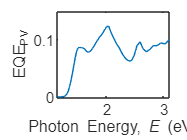

figure
plot( photon_energies , EQE_PV_data)
xlabel('Photon Energy,{\it E} (eV)');
ylabel('EQE_{PV}');

Following this, the natural logarithm of the normalised photovoltaic external quantum efficiency and the corresponding apparent Urbach energy are determined, with numerical differentiation being employed to calculate the latter.

norm_EQE_PV_data = EQE_PV_data / EQE_FSP;               % Normalise data w.r.t. value at FSP

ln_EQE_PV_data = log( norm_EQE_PV_data );
d_ln_EQE_PV_dE = diff( ln_EQE_PV_data )./ diff( photon_energies );
E_U_apps = 1./d_ln_EQE_PV_dE;

 These quantities are then plotted in a new figure. 

figure;                                   % Begin a new figure
yyaxis("left");                           % Multiple y-axes
plot( photon_energies, ln_EQE_PV_data );
ylabel('ln(EQE_{PV}/EQE_{FSP})');
xlabel('Photon Energy,{\it E} (eV)');

hold on
yyaxis right;
ylabel('Apparent Urbach Energy,{\it E}_{U}^{app} (meV)');
plot( photon_energies(2:end) , E_U_apps );
ylim( [ k_BT * 0.5 , k_BT * 4] );          % Specify vertical scale to consider E_U^app about k_BT
ax = gca;            
ax.YTickLabel = ax.YTick * 1000;

The index of the minimal lower limit of the fitting is identified to adjust the horizontal scale of the graph (with the upper limit being given by the first saturation peak):

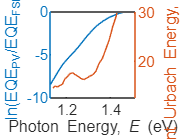

hold on
xlim( [photon_energies( index_E_tra_float_min ) photon_energies( index_E_FSP ) ] )

----- **Part III** ----- 

Using some initial guess for the parameters-of-interest, as well as the input estimates for the minimum and maximum of the fittings, the curve fitting toolbox is applied. For each combination of minimum and maximum fitting limit, a row of an empty array ('extracted_vals') will be popultated by seven values: (i) The lower limit of the fitting in eV, (ii) the upper limit of the fitting in eV, (iii) the extracted alpha_sat in 1/nm, (iv) the extracted E_opt in eV, (v) the extracted sigma_S in eV, (vi) the goodness-of-fit parameter 'Adjusted R-Square', and (vii) the goodness-of-fit parameter 'Root Mean Square Error (RMSE)'.

parameters_guess = [0.01 1.6 0.05];
extracted_vals = zeros( 7 , length( upper_fitting_indices ) , length( lower_fitting_indices ) );

for i = 1 : length ( upper_fitting_indices )

    for j = 1 : length( lower_fitting_indices )

        lower_fitting_index = lower_fitting_indices( j );
        upper_fitting_index = upper_fitting_indices( i );        
       
        if upper_fitting_index + minimum_num_data_points > lower_fitting_index      % conduct fitting if minimum number of data points is satisfied

            extracted_vals( 1 , i , j ) = photon_energies(lower_fitting_index);
            extracted_vals( 2 , i , j ) = photon_energies(upper_fitting_index);
    
            try
                photon_energies_RoI = photon_energies( lower_fitting_index : upper_fitting_index );
        
                ln_EQE_PVs_RoI = ln_EQE_PV_data( lower_fitting_index : upper_fitting_index );
        
                SE_EQE = @( alpha_sat, E_SE0 , sigma_S , x ) log( ( 1-exp(-( alpha_sat*d_AL/2)*(exp((x-E_SE0+(sigma_S^2/(2*k_BT)))/k_BT).*(erfc((x-E_SE0+(sigma_S^2/k_BT))/(sigma_S*sqrt(2))))+1+erf((x-E_SE0)/(sigma_S*sqrt(2)))))) / ( 1 - exp( - alpha_sat * d_AL ) ) ) ;
        
                opt = fitoptions('Method','NonlinearLeastSquares',...
                    'Lower',[0 0 0],...            % coefficient lower boundaries
                    'Upper',[2 2.5 0.2],...       % coefficient upper boundaries
                    'StartPoint',parameters_guess);
        
                ft = fittype(SE_EQE,'options',opt);
        
                [fitted_curve, GoF] = fit(photon_energies_RoI,ln_EQE_PVs_RoI,ft);
            
                extracted_vals( 3:7 , i , j ) = [fitted_curve.alpha_sat fitted_curve.E_SE0 fitted_curve.sigma_S GoF.adjrsquare GoF.rmse];
            catch ME
            end
        end
    end
end


Some fittings may fail, resulting in some elements of the matrix "extracted_vals" having the value "nan", this must be removed and the matricse reshaped before analysing the data. 

extracted_vals( isnan( extracted_vals ) ) = 0;

for i=1:length(upper_fitting_indices)
    for j=1:length(lower_fitting_indices)
        for l=1:7
            if extracted_vals( l , i , j ) == 0
                extracted_vals( : , i , j ) = 0;
            end
        end
    end
end

extracted_vals = nonzeros(extracted_vals);
extracted_vals = reshape( extracted_vals , 7 , []);
extracted_vals = transpose(extracted_vals);

The rows are sorted according to their adjusted R-square value.

sorted_extracted_vals = sortrows( extracted_vals , 6 , 'descend' );

col_header={'Minimum Photon Energy of Fitting (eV)','Maximum Photon Energy of Fitting (eV)','alpha_sat (1/nm)','E_opt (eV)','sigma_S (eV)','Adjusted R-Square','RMSE'};

xlswrite(output_data_filename,sorted_extracted_vals,string('All_fits_')+string(d_AL)+string('nm'),'A2')

xlswrite(output_data_filename,col_header,string('All_Fits_')+string(d_AL)+string('nm'),'A1')


N_fittings = length( extracted_vals );
twentieth_percentile = round(N_fittings/5);

Finally, the script outputs seven types of results to the output Excel file; firstly, a 'raw average' is computed for all fittings - this value is likely to be innacurate due to the effects of CT states (i.e., lack of optimisation of fitting limits). Secondly, the parameters that describe the best fitting (in terms of adjusted R-square) are outputted. Following this, the averages of each twentieth percentile of the fittings (in terms of adjusted R square) are computed and outputted. For each output, the standard error is also computed and outputted. We find the top 20% of fittings (in terms of adjusted R-square) give the most accurate value for the adjusted R-square, with some fits slightly over-estimating and some fits slightly under-estimating sigma_S, but the average being more accurate.

raw_average = mean(extracted_vals,1);
std_err_raw_average = std(extracted_vals)/sqrt(N_fittings);

best_R_square_fitting_vals = squeeze(sorted_extracted_vals(1,:));
top_20_percent_average = mean(sorted_extracted_vals(1:twentieth_percentile,:));
std_err_top_20_percent = std(sorted_extracted_vals(1:twentieth_percentile,:))/sqrt(twentieth_percentile);

range_20_40_percent_average = mean(sorted_extracted_vals(twentieth_percentile:2*twentieth_percentile,:));
std_err_20_40_percent = std(sorted_extracted_vals(twentieth_percentile:2*twentieth_percentile,:))/sqrt(twentieth_percentile);

range_40_60_percent_average = mean(sorted_extracted_vals(2*twentieth_percentile:3*twentieth_percentile,:));
std_err_40_60_percent = std(sorted_extracted_vals(2*twentieth_percentile:3*twentieth_percentile,:))/sqrt(twentieth_percentile);

range_60_80_percent_average = mean(sorted_extracted_vals(3*twentieth_percentile:4*twentieth_percentile,:));
std_err_60_80_percent = std(sorted_extracted_vals(3*twentieth_percentile:4*twentieth_percentile,:))/sqrt(twentieth_percentile);

bottom_20_percent_average = mean(sorted_extracted_vals(4*twentieth_percentile:N_fittings,:));
std_err_bottom_20_percent = std(sorted_extracted_vals(4*twentieth_percentile:N_fittings,:))/sqrt(N_fittings-4*twentieth_percentile);

average_col_header={'Result Type','Minimum Photon Energy of Fitting (eV)','Maximum Photon Energy of Fitting (eV)','alpha_sat (1/nm)','E_opt (eV)','sigma_S (eV)','Adjusted R-Square','RMSE'};
row_header={'Average of All Fits','Best Fit','Average of Top 20%','Average of Middle 20-40%','Average of Middle 40-60%','Average of Middle 60-80%','Average of Bottom 20%'};
row_header=transpose(row_header);

Output_Array = zeros(7,7);
Output_Array(1,:)=raw_average;
Output_Array(2,:)=best_R_square_fitting_vals;
Output_Array(3,:)=top_20_percent_average;
Output_Array(4,:)=range_20_40_percent_average;
Output_Array(5,:)=range_40_60_percent_average;
Output_Array(6,:)=range_60_80_percent_average;
Output_Array(7,:)=bottom_20_percent_average;

xlswrite(output_data_filename,average_col_header,string('Averages_')+string(d_AL)+string('nm'),'A1')

xlswrite(output_data_filename,row_header,string('Averages_')+string(d_AL)+string('nm'),'A2')
xlswrite(output_data_filename,Output_Array,string('Averages_')+string(d_AL)+string('nm'),'B2')

Output_err_Array = zeros(7,7);
Output_err_Array(1,:)=std_err_raw_average;
Output_err_Array(3,:)=std_err_top_20_percent;
Output_err_Array(4,:)=std_err_20_40_percent;
Output_err_Array(5,:)=std_err_40_60_percent;
Output_err_Array(6,:)=std_err_60_80_percent;
Output_err_Array(7,:)=std_err_bottom_20_percent;

err_col_header={'Result Type','Std Err in Minimum Photon Energy of Fitting (eV)','Std Err in Maximum Photon Energy of Fitting (eV)','Std Err in alpha_sat (1/nm)','Std Err in E_opt (eV)','Std Err in sigma_S (eV)','Std Err in Adjusted R-Square','Std Err in RMSE'};

xlswrite(output_data_filename,err_col_header,string('Errors_')+string(d_AL)+string('nm'),'A1')

xlswrite(output_data_filename,row_header,string('Errors_')+string(d_AL)+string('nm'),'A2')
xlswrite(output_data_filename,Output_err_Array,string('Errors_')+string(d_AL)+string('nm'),'B2')

beep;